# Simulate Gnaguli and Simoncelli 2016

## Traditional assumption:

 For a stimulus variable "S" that takes values {s1, s2, ..., sn}, a neuronal population, with different selectivieity, covers the full range of stimulus values with equal weight. The following quantities are homogeneous: number (tuning center), selectivity (tuning width), and noise properties of neurons in the underlying neural population.

## New assumptoins:

(based on the measurement of the neuronal population and behavioral threshold, e.g. takes different contrast as different stimulus values). To explain why this is the case and how various forms of heterogeneity relate to each other.

## Construct homegeneous population response (with constraints N and R):

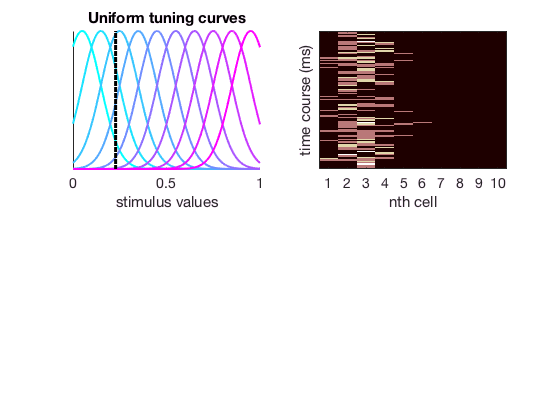

% STIMULUS PROPERTIES ---------------------------------------------
% A rstimulus random variable S, that can take values from {s1, s2, ..., sn}
S_min = 0; 
S_max = 1;
s     = round(rand, 3); % a random number between 0 and 1, so S is uniformly distributed between 0 and 1
dx    = 0.001;
x     = S_min + dx : dx: S_max;

% NEURONAL TUNING  ----------------------------------------------
N         = 10; % number of neurons to encode the stimulus value s
tc        = []; % construct tuning curves
tc.center = linspace(S_min, S_max, N);
tc.width  = 0.1;
tc.grid   = linspace(S_min, S_max, S_max/dx);
tc.center = tc.grid(50 : 100 : S_max/dx);

for k = 1 : N, tc.curve(k, :)  = normpdf(tc.grid, tc.center(k), tc.width); end
tc.curve = tc.curve ./max(tc.curve(:)); % normalize the tuning curve amplitude to the max:

% CONSTRUCT RESPONSE PROFILE --------------------------------------
T  = 0.1; % SECOND,
t  = 0.001 : 0.001 : T; t_lth = length(t);
R  = 2;   % sum of the poisson rate across cells 


% compute each neuron's repsonse to the randomly selected stimulus
rsp = []; 
for k = 1 : N,  lambda(k) = tc.curve(k, s * (S_max/dx)); end
if sum(lambda) > R, lambda = lambda .* (R/sum(lambda)); end
   
for k =  1: N, rsp(k, :) = poissrnd(lambda(k), [1, t_lth]); end

% Visualize homogeneous population response------------------------
figure (1), clf,
% plot tuning curves
subplot(2, 2, 1), set(gca, 'colororder', cool(N)), hold on, plot(tc.grid, tc.curve', 'linewidth', 2),
plot([s, s], [0, 1], 'k:', 'linewidth', 3)
set(gca, 'ytick', ''), xlabel('stimulus values'), set(gca, 'fontsize', 14), title('Uniform tuning curves'), box off, 

% plot individual cell responses
subplot(2, 2, 2), colormap pink, imagesc(rsp'), set(gca, 'xtick', 1 : 10), xlabel('nth cell'), set(gca, 'fontsize', 14),
set(gca, 'ytick', ''), ylabel('time course (ms)')    

## Construct an inhomogeneous population of neuroral responses (with non uniformstimulus variable, tuning curve center and amplitude, and repsonse gain)

## Step 1 : Warp the tuning curve distribution and gain

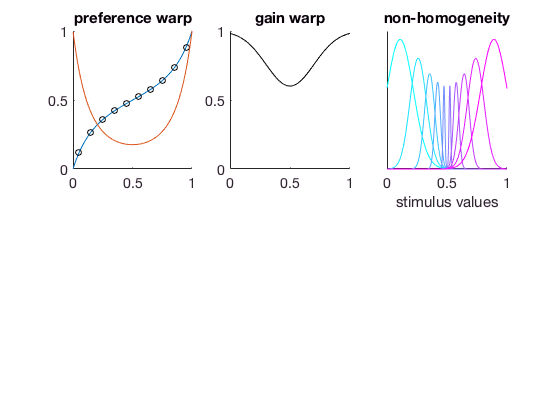

% warp the tuning curve distribution, using a logistic distribution
warp = [];

% generate Cauchy distribution
element(1, :) = normpdf(x, 0.5, .3);
element(2, :) = normpdf(x, 0.5, .2);
warp.lc_pdf = element(1, :)./element(2, :); warp.lc_pdf = warp.lc_pdf/sum(warp.lc_pdf);
warp.lc_cdf = cumsum(warp.lc_pdf);
warp.gain = -(normpdf(x, 0.5, 0.2)).*0.2; warp.gain = warp.gain + 1;

ihtc = [];
ihtc.center = warp.lc_cdf(50 : 100 : S_max/dx);

% construct tuning curves:
for k = 1 : N, 
    dist_2_cent = abs((ihtc.center(k)-0.5)) * 3;
    ihtc.curve(k, :) = normpdf(tc.grid, ihtc.center(k), tc.width * dist_2_cent); 
    ihtc.curve(k, :) = ihtc.curve(k, :)./max(ihtc.curve(k, :));
    % multiply by the gain
    ihtc.curve(k, :) = ihtc.curve(k, :) .* warp.gain;
end
 
 % Visualize --------------------------------------------------------
 figure (2), clf
 subplot(2, 3, 1), plot(x, warp.lc_cdf), hold on, plot(tc.center, ihtc.center, 'ko'), plot(x, warp.lc_pdf./max(warp.lc_pdf)), box off, title('preference warp'), set(gca, 'fontsize', 14)
 subplot(2, 3, 2), plot(x, warp.gain, 'k-'), ylim([0, 1]), box off, title('gain warp'), set(gca, 'fontsize', 14)
 subplot(2, 3, 3), set(gca, 'colororder', cool(N)), hold on, plot(x, ihtc.curve'), set(gca, 'ytick', ''), title('non-homogeneity'), set(gca, 'fontsize', 14), 
 xlabel('stimulus values')